https://alessandromastrofini.it/deep-learning-segmentazione/

# Initialization

## Path

clear all; close all; 

% set current file path 
filePath = matlab.desktop.editor.getActiveFilename;
pathDivided=strsplit(filePath,'\');
newPath=erase(filePath,pathDivided(end));
dataPath=strcat(newPath,'dataset');
% set folder with net syntax
imds = imageDatastore(strcat(newPath,'dataset\FRAME_TRAIN')); % link for training frame
pxds = pixelLabelDatastore(strcat(newPath,'dataset\GT_TRAIN'),["N","B"],[0 1]); % link for GT images
f_test=dir(strcat(dataPath,'/FRAME_TEST_SEG/*.tiff'));
gt_train=dir(strcat(dataPath,'/GT_TEST/*.tiff'));

addpath(strcat(newPath,'functions')); %set path for functions

## ResNet50

clear pximds lgraph
net=resnet50;
numClasses=2; % foreground and background
imageSize=net.Layers(1).InputSize; %read size directly from net
augmenter = imageDataAugmenter('RandRotation',[0 360],'RandXReflection',true,'RandXTranslation',[-20 20],'RandYTranslation',[-20 20]);
pximds = pixelLabelImageDatastore(imds,pxds,'DataAugmentation',augmenter,'OutputSize',imageSize,'ColorPreprocessing','gray2rgb');
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet50"); 
% balance predominance of 0
tbl = countEachLabel(pximds);
totalNumberOfPixels = sum(tbl.PixelCount);
frequency = tbl.PixelCount / totalNumberOfPixels;
classWeights = 1./frequency;
pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

[net_resnet50, info_resnet50, FM_test_resnet50,compTime_resnet50]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       24.58% |       0.8217 |          0.0100 |
|       8 |          50 |       00:01:05 |       90.51% |       0.2235 |          0.0100 |
|      15 |         100 |       00:02:12 |       93.28% |       0.1437 |          0.0100 |
|      22 |         150 |       00:03:23 |       93.38% |       0.1345 |          0.0100 |
|      29 |         200 |       00:04:35 |       94.45% |       0.1000 |          0.0100 |
|      36 |         250 |       00:05:50 |       94.81% |       0.1017 |          0.0100 |
|      40 |         280 |  

disp('Test for ResNet50')

Test for ResNet50


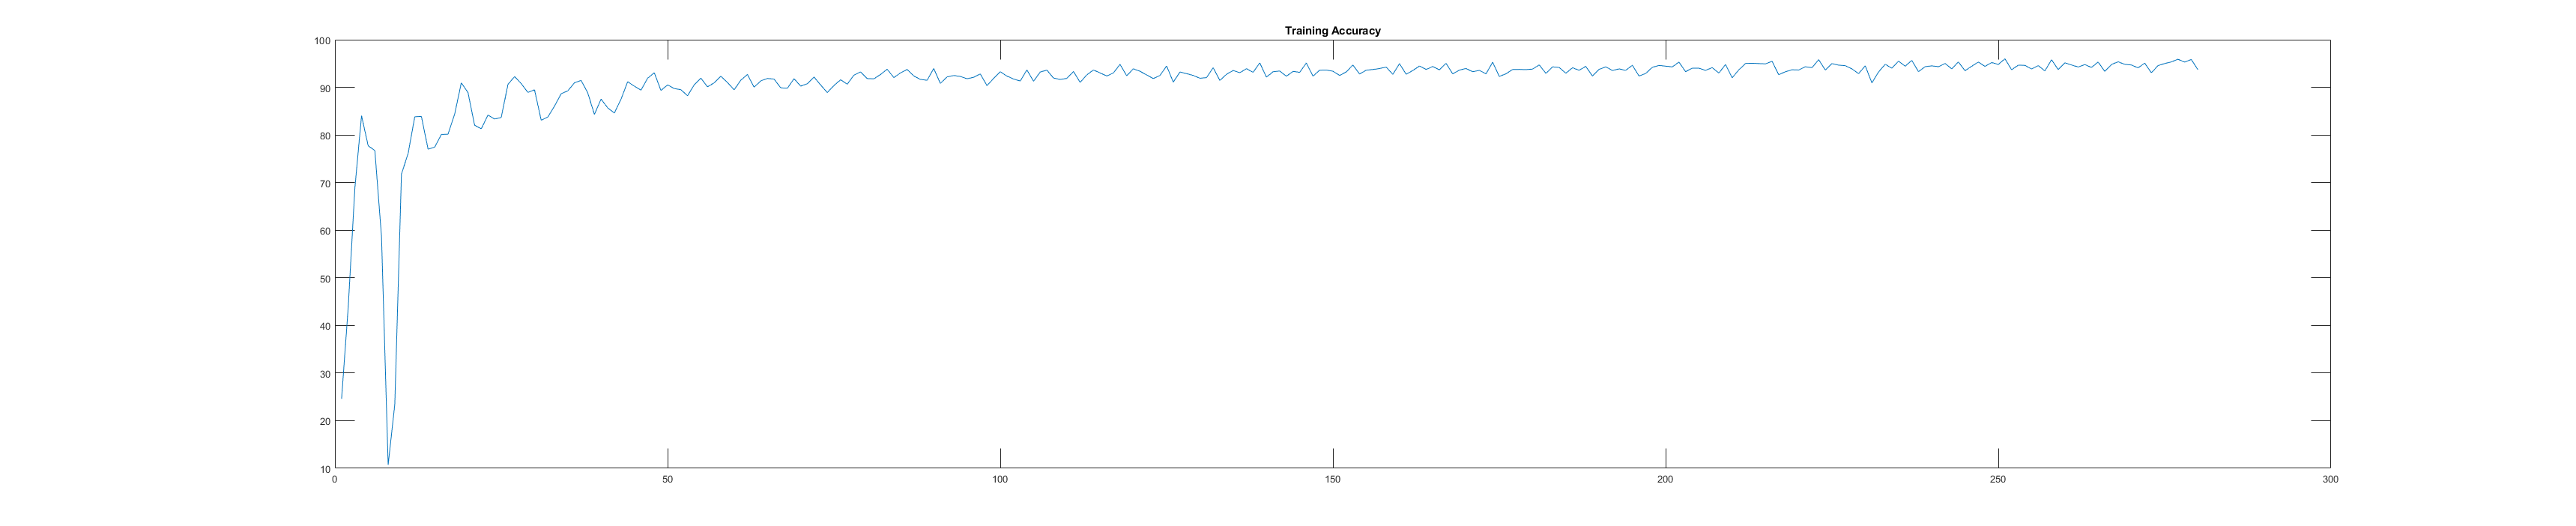

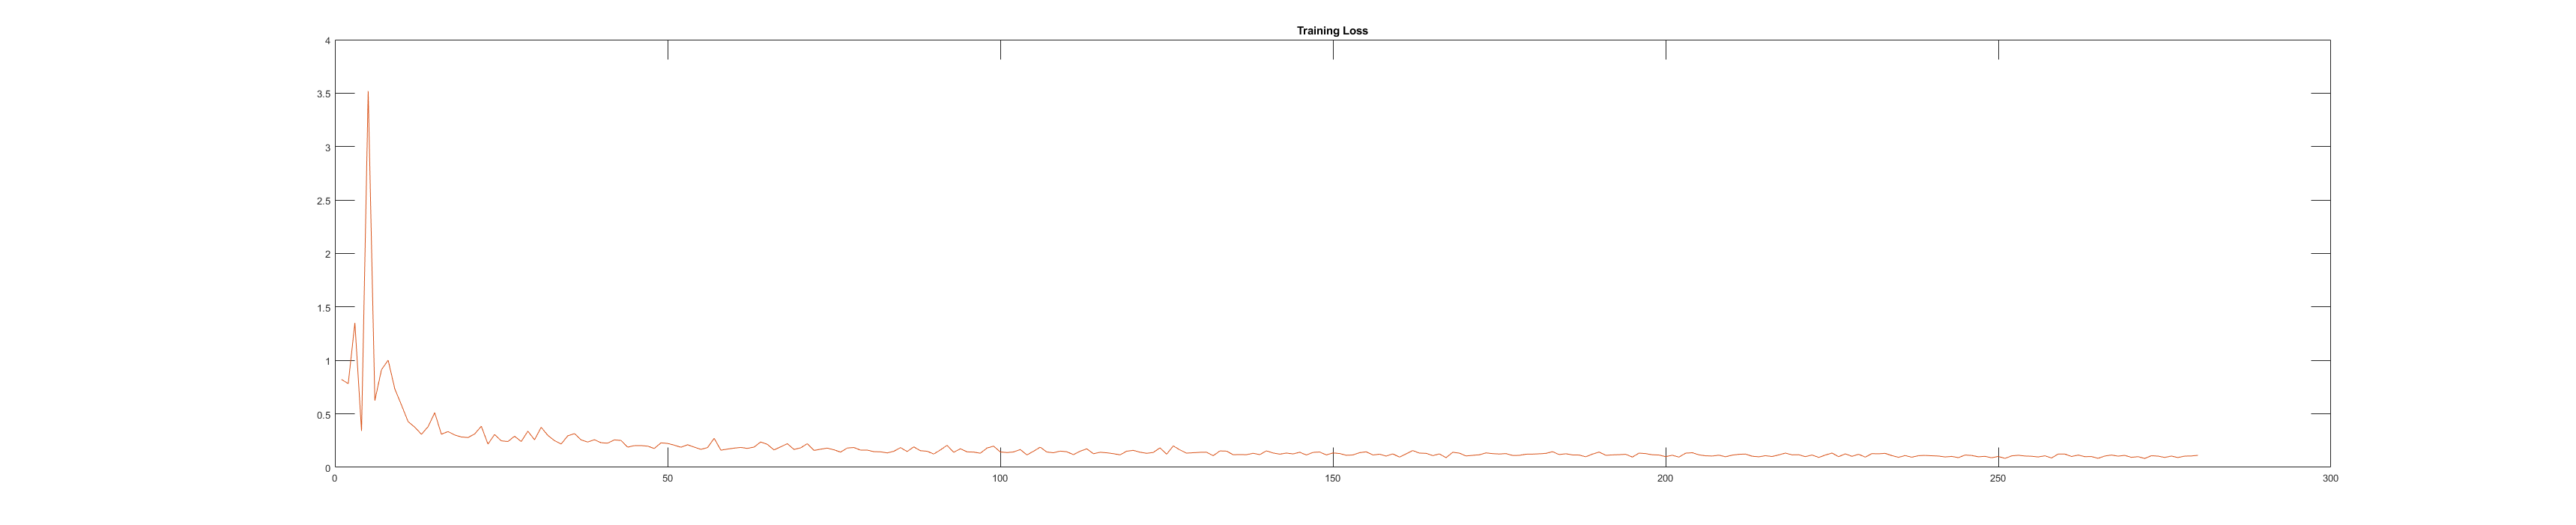

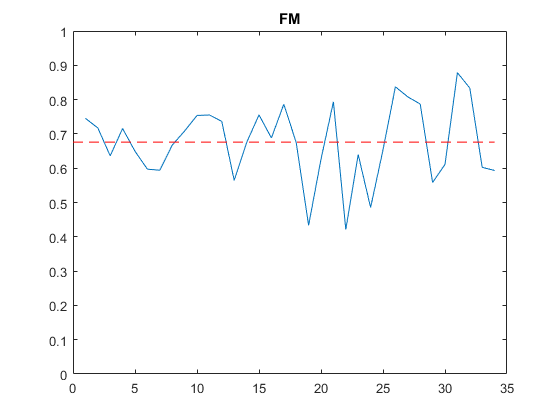

FM mean: 0.67601
FM max: 0.87846
FM min: 0.42133
FM std: 0.11032
accuracy: 93.704
loss: 0.1121


[accuracy_resnet50,loss_resnet50,FM_mean_resnet50]=figureAccAndLoss(info_resnet50,FM_test_resnet50);

## ResNet18

clear pximds lgraph
[pximds,lgraph]=prepareMyNet(resnet18,'resnet18',imds,pxds);

resnet18 ready


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       42.65% |       0.7952 |          0.0100 |
|       8 |          50 |       00:00:35 |       87.08% |       0.2230 |          0.0100 |
|      15 |         100 |       00:01:07 |       90.39% |       0.1718 |          0.0100 |
|      22 |         150 |       00:01:39 |       92.95% |       0.1439 |          0.0100 |
|      29 |         200 |       00:02:12 |       94.48% |       0.1080 |          0.0100 |
|      36 |         250 |       00:02:46 |       93.80% |       0.1319 |          0.0100 |
|      40 |         280 |  

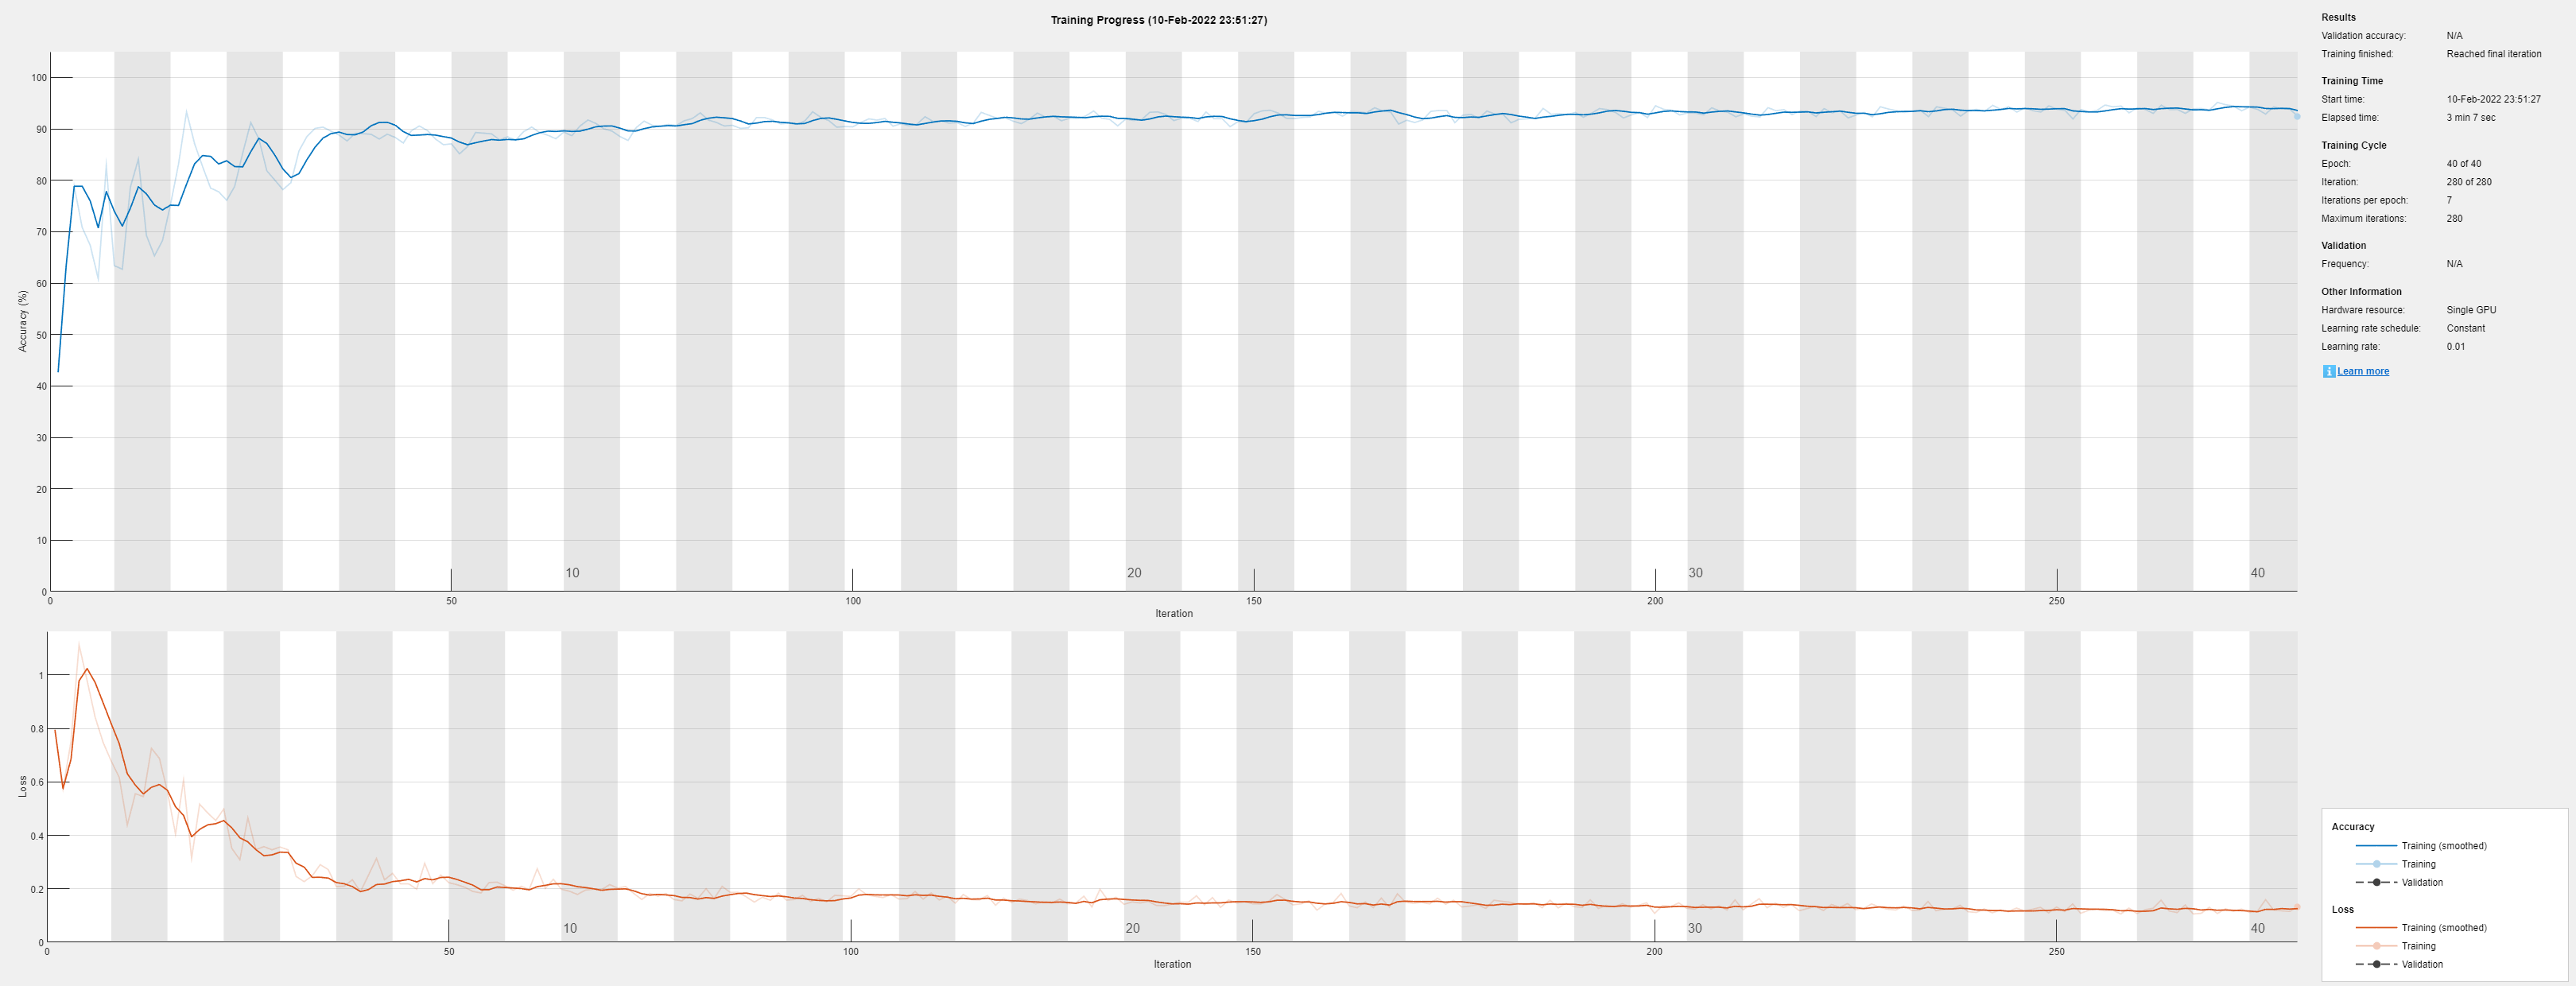

[net_resnet18, info_resnet18, FM_test_resnet18,compTime_resnet18]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

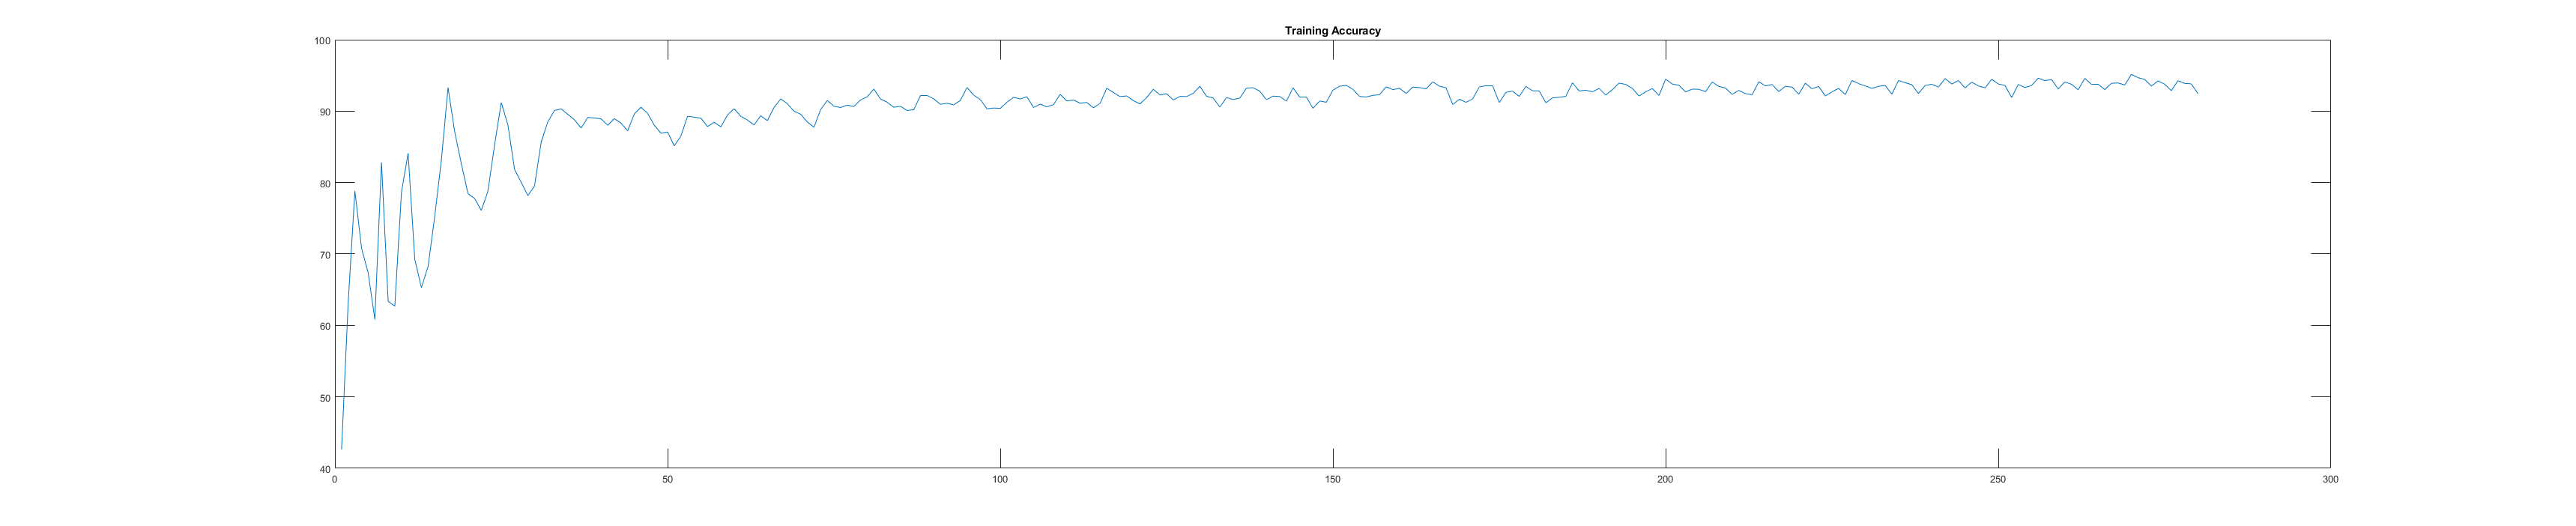

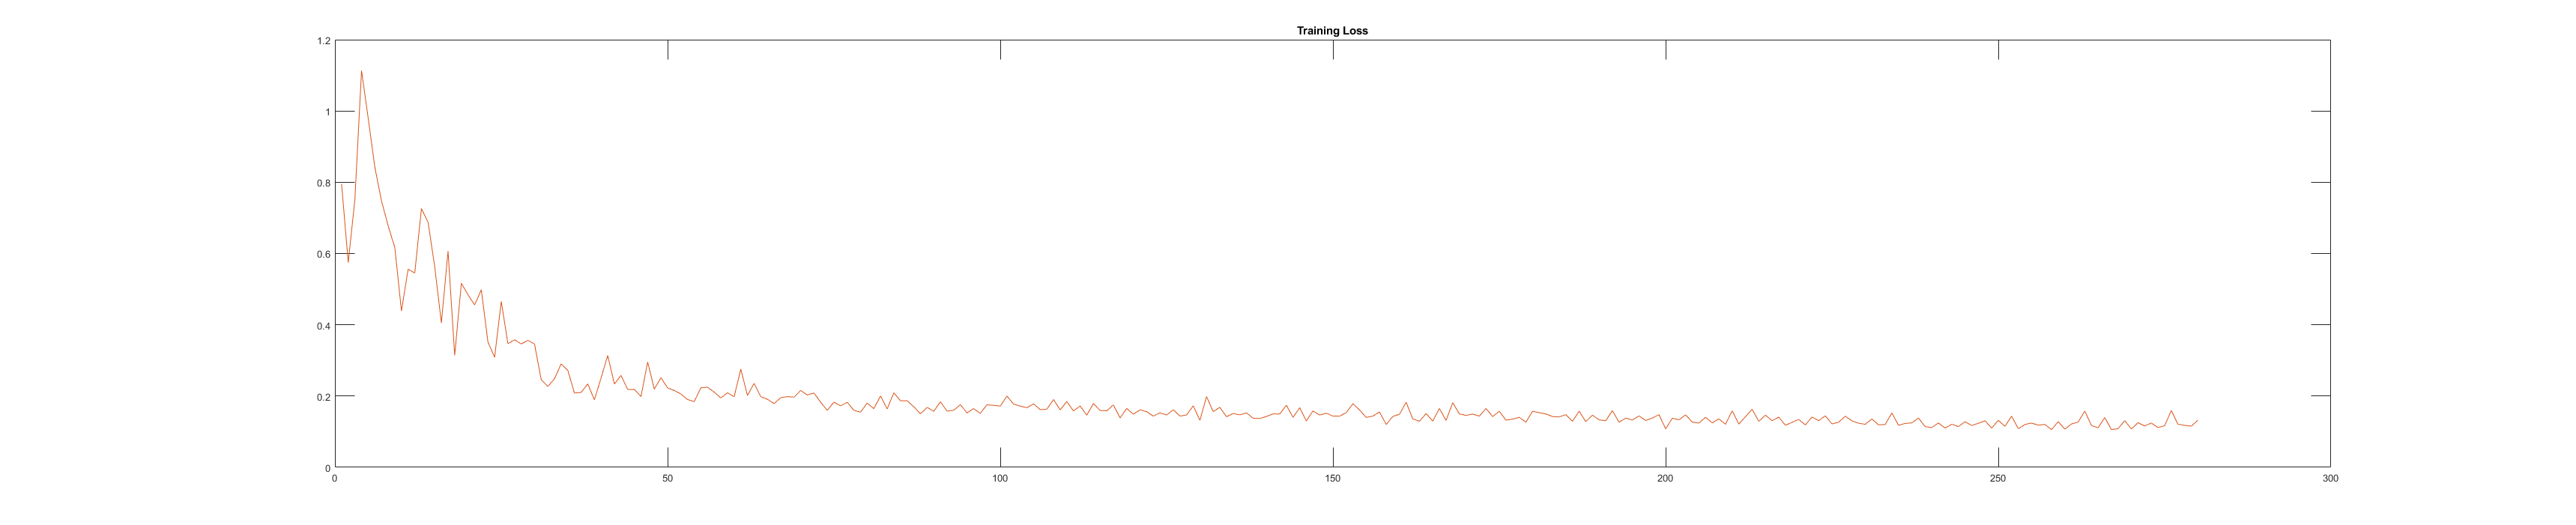

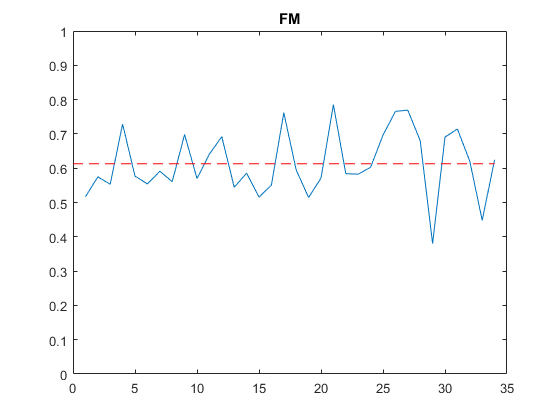

FM mean: 0.61298
FM max: 0.78523
FM min: 0.38018
FM std: 0.094259
accuracy: 92.4626
loss: 0.13234


accuracy_resnet18 = 92.4626

loss_resnet18 = 0.1323

FM_mean_resnet18 = 0.6130

[accuracy_resnet18,loss_resnet18,FM_mean_resnet18]=figureAccAndLoss(info_resnet18,FM_test_resnet18)

## MobileNetv2

clear pximds lgraph
[pximds,lgraph]=prepareMyNet(mobilenetv2,'mobilenetv2',imds,pxds);

mobilenetv2 ready


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       74.38% |       1.0295 |          0.0100 |
|       8 |          50 |       00:00:42 |       90.81% |       0.2219 |          0.0100 |
|      15 |         100 |       00:01:18 |       93.73% |       0.1292 |          0.0100 |
|      22 |         150 |       00:01:55 |       92.93% |       0.1342 |          0.0100 |
|      29 |         200 |       00:02:32 |       94.45% |       0.1148 |          0.0100 |
|      36 |         250 |       00:03:10 |       94.38% |       0.1127 |          0.0100 |
|      40 |         280 |  

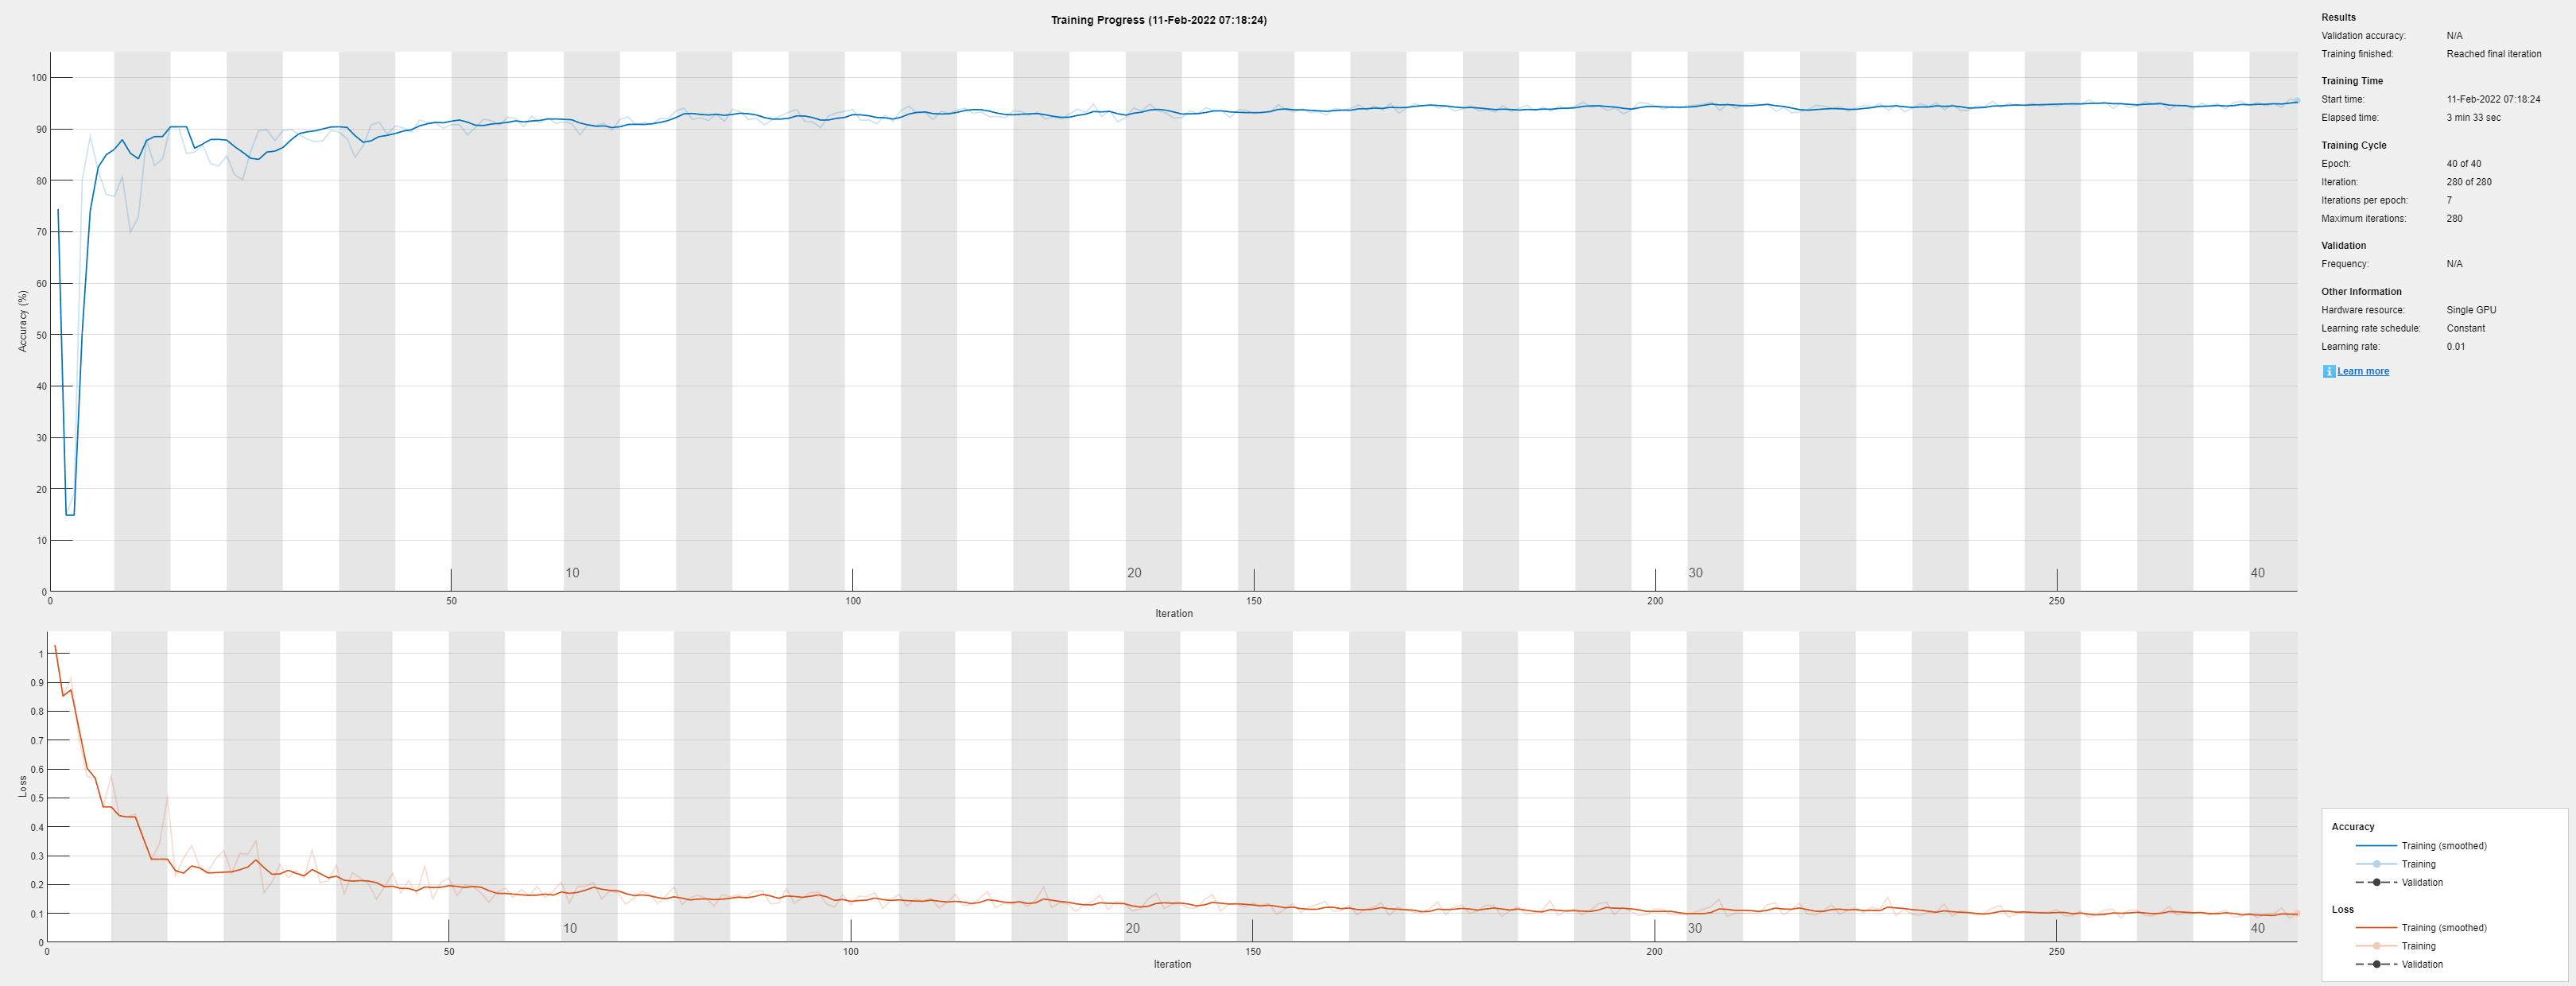

[net_mobilenetv2, info_mobilenetv2, FM_test_mobilenetv2,compTime_mobilenetv2]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

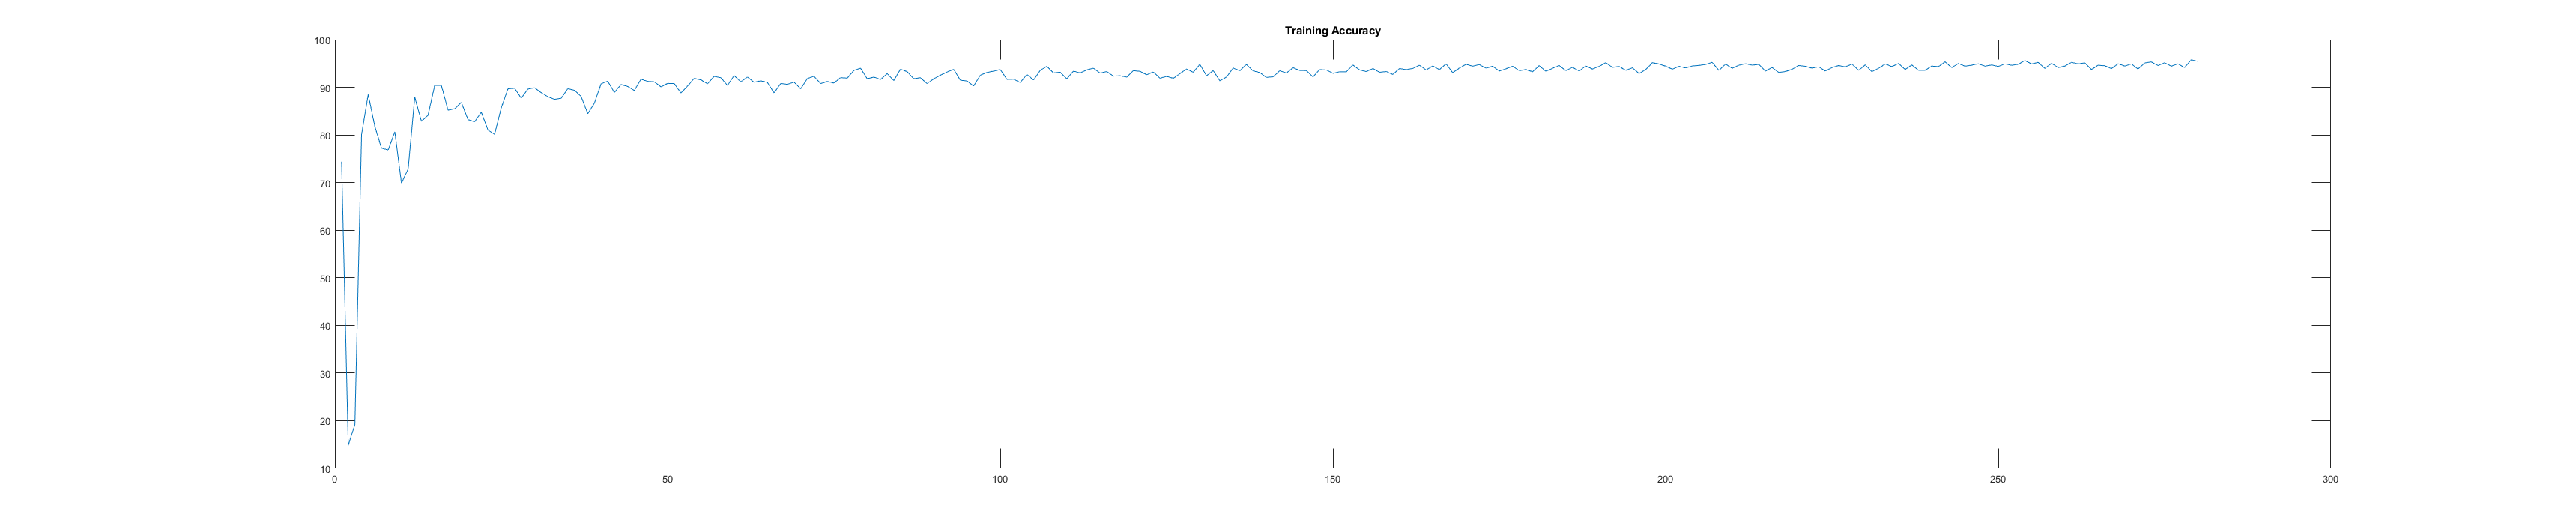

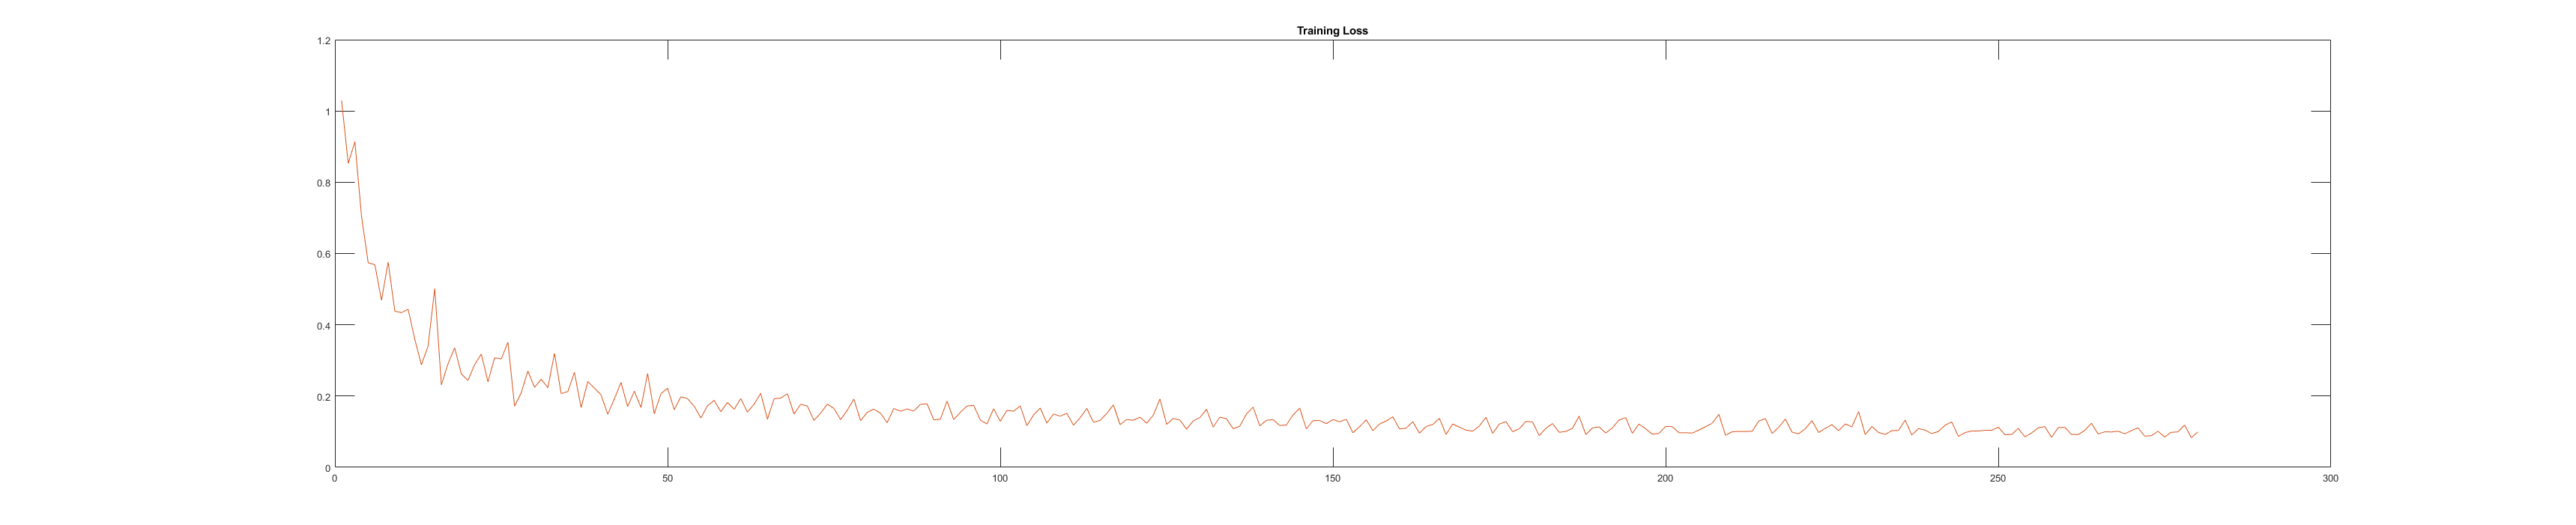

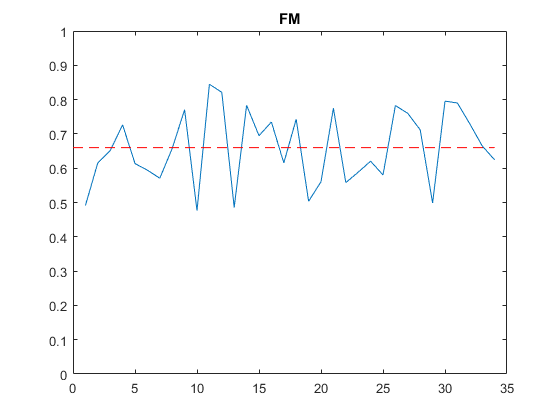

FM mean: 0.65985
FM max: 0.84471
FM min: 0.4765
FM std: 0.10771
accuracy: 95.4562
loss: 0.099173


accuracy_mobilenetv2 = 95.4562

loss_mobilenetv2 = 0.0992

FM_mean_mobilenetv2 = 0.6598

[accuracy_mobilenetv2,loss_mobilenetv2,FM_mean_mobilenetv2]=figureAccAndLoss(info_mobilenetv2,FM_test_mobilenetv2)

## Xception

clear pximds lgraph
[pximds,lgraph]=prepareMyNet(xception,'xception',imds,pxds);

xception ready


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       57.05% |       0.8496 |          0.0100 |
|       8 |          50 |       00:02:59 |       88.77% |       0.2023 |          0.0100 |
|      15 |         100 |       00:06:03 |       91.56% |       0.1597 |          0.0100 |
|      22 |         150 |       00:09:14 |       93.54% |       0.1647 |          0.0100 |
|      29 |         200 |       00:12:49 |       93.20% |       0.1293 |          0.0100 |
|      36 |         250 |       00:17:55 |       94.12% |       0.1448 |          0.0100 |
|      40 |         280 |  

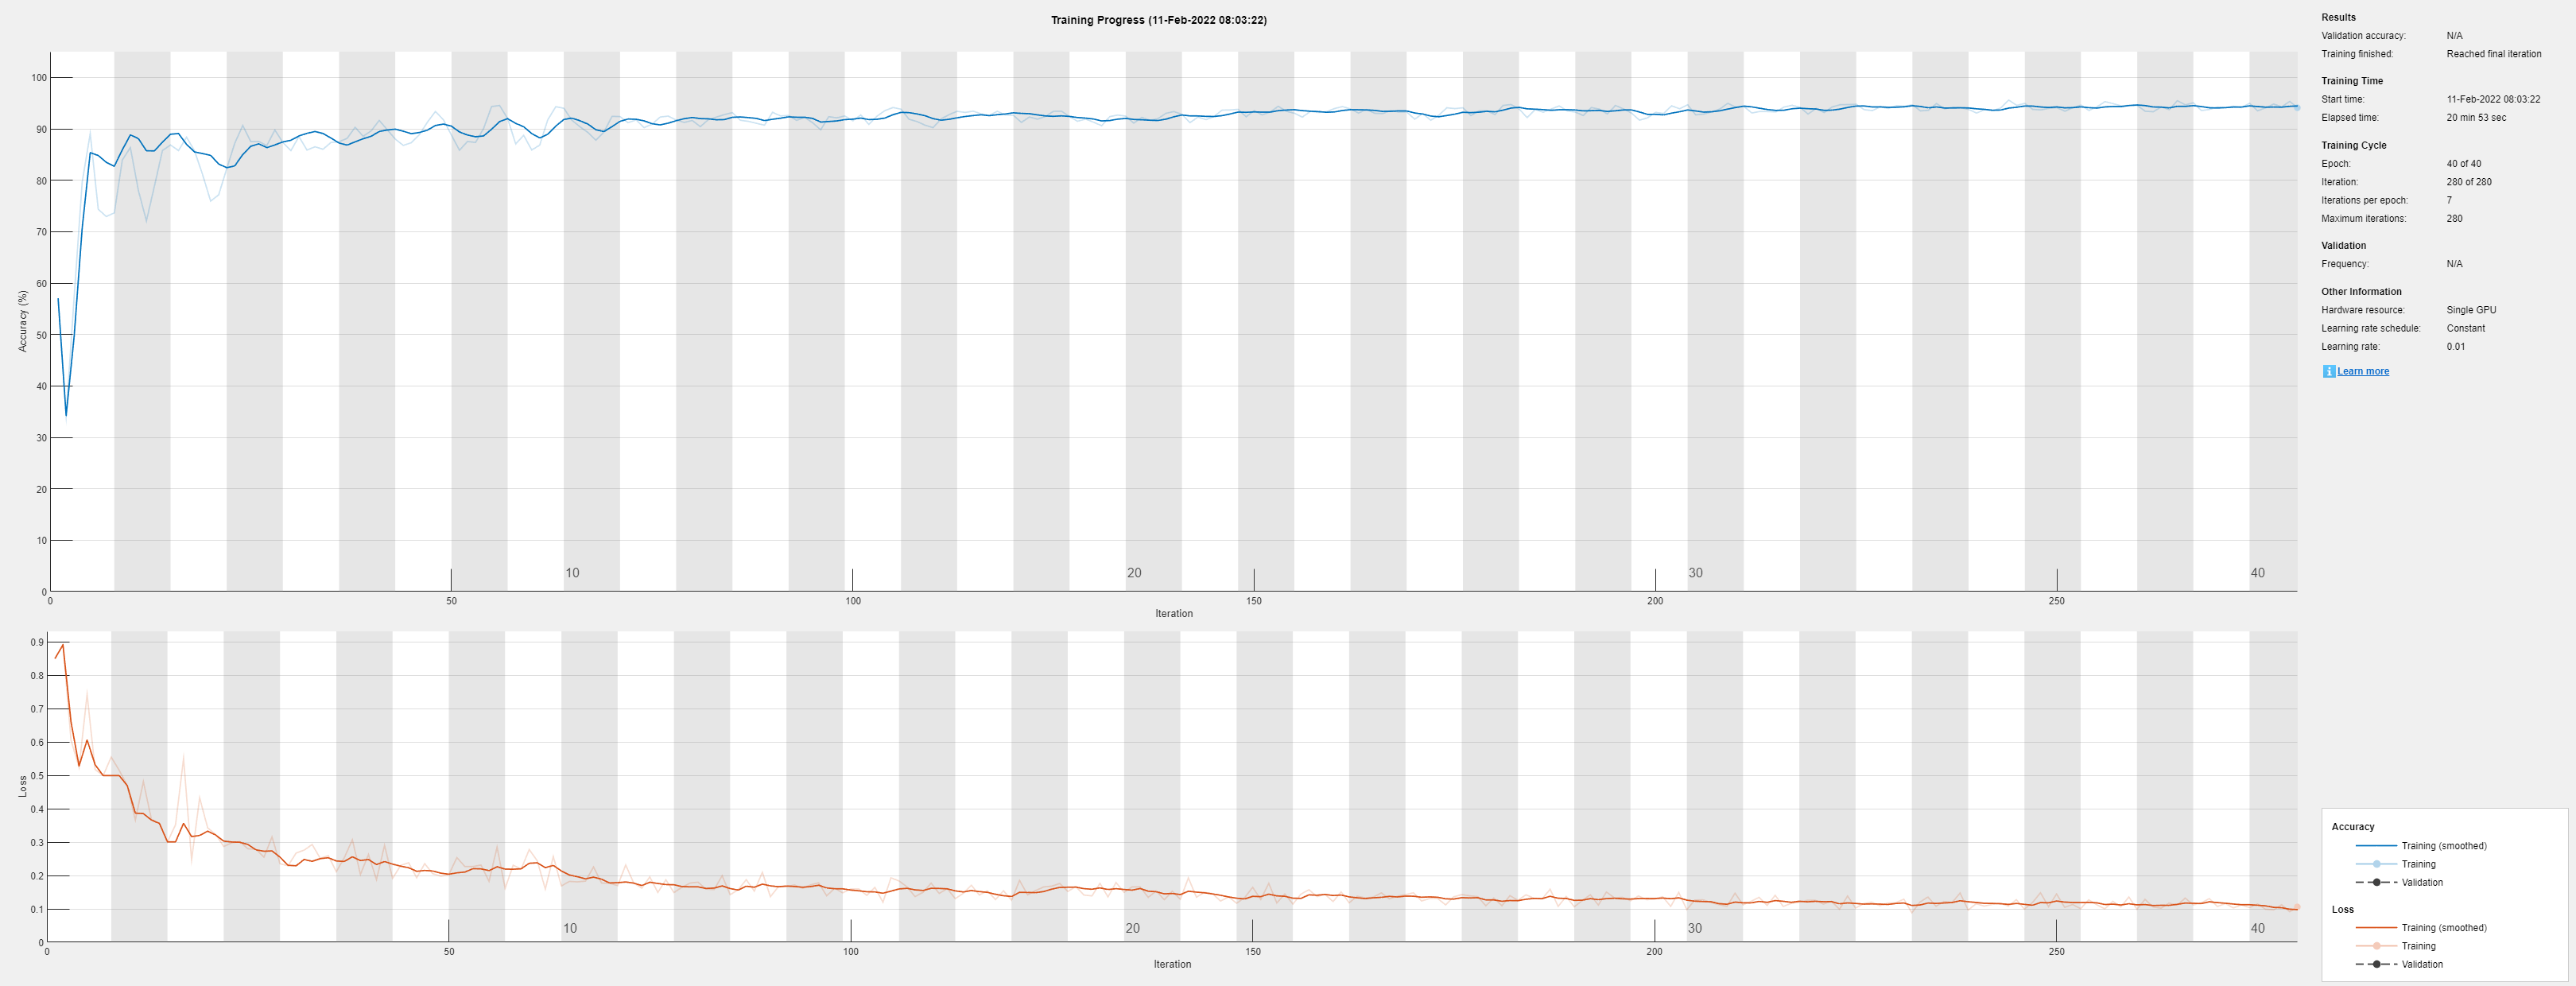

img scaled


[net_xception, info_xception, FM_test_xception,compTime_xception]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

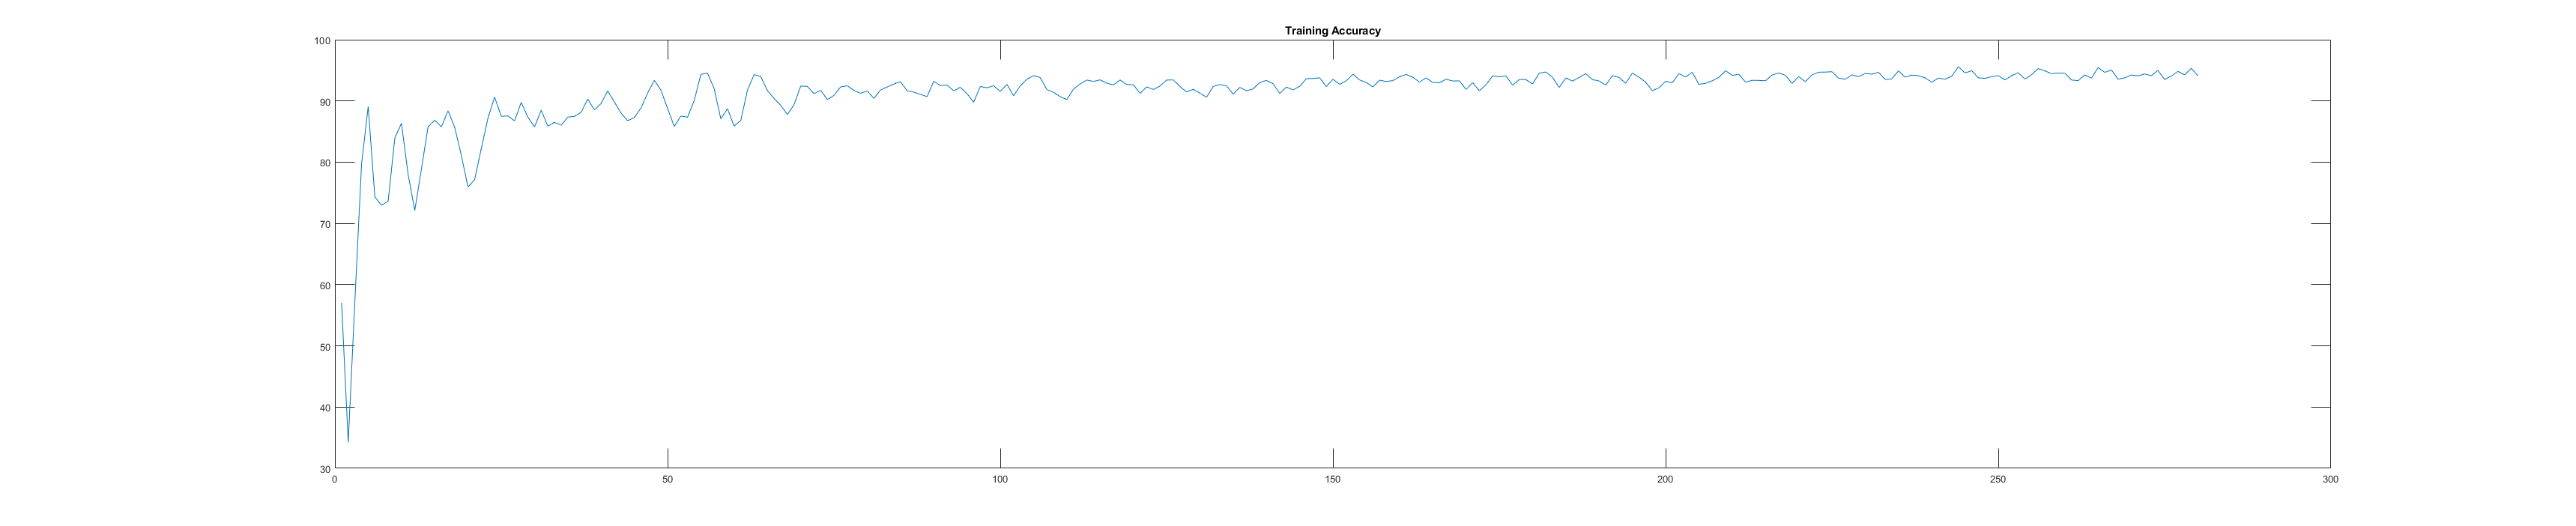

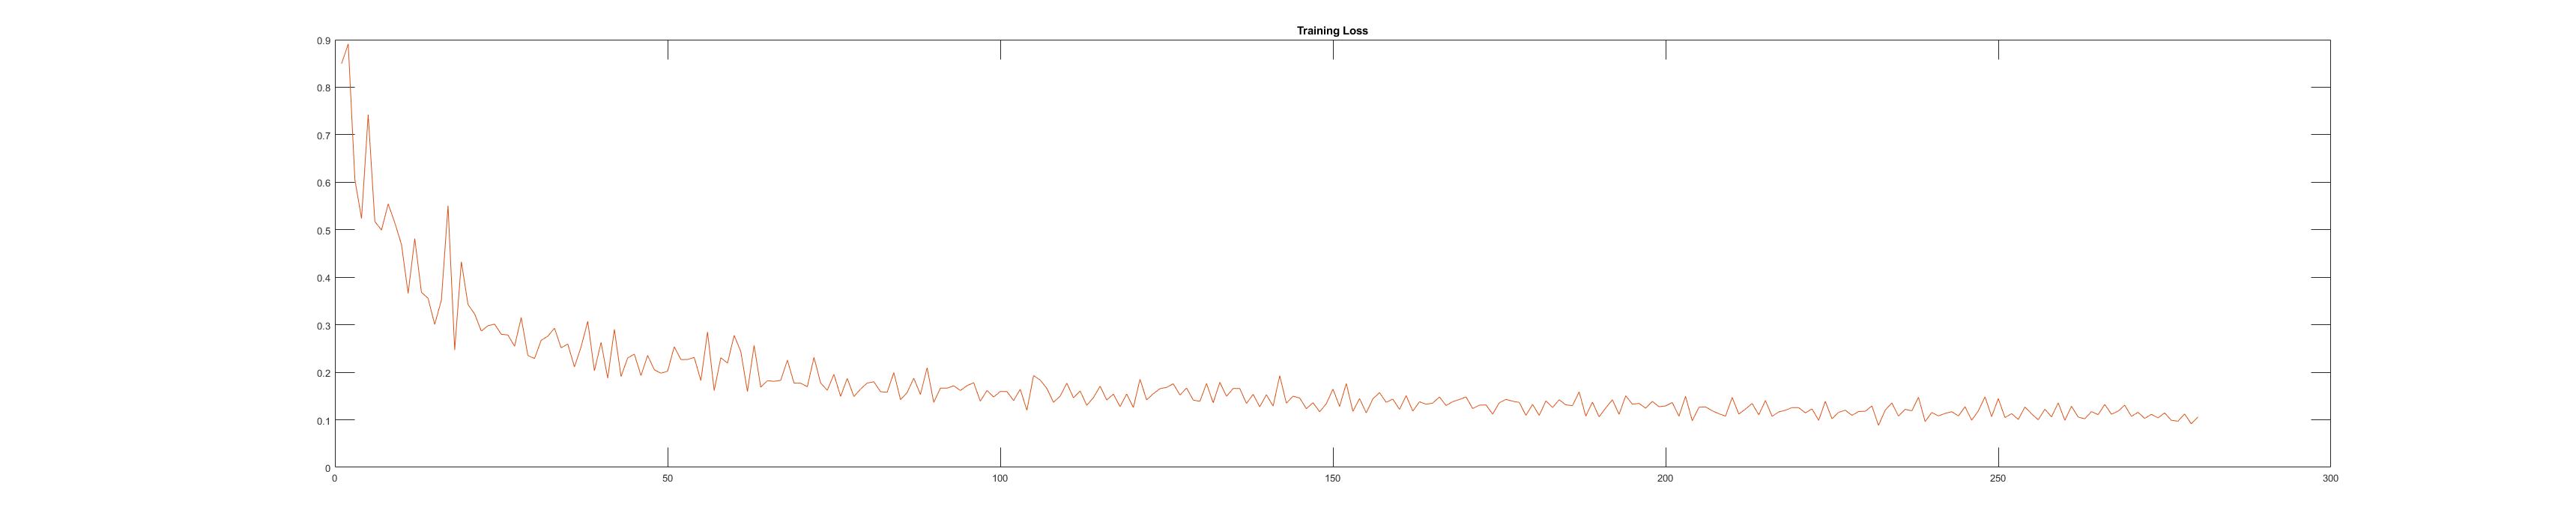

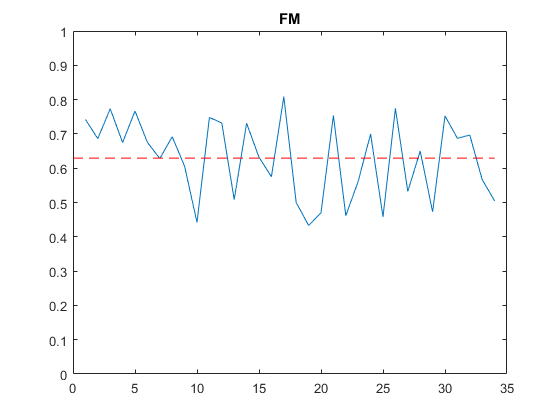

FM mean: 0.62934
FM max: 0.80844
FM min: 0.43316
FM std: 0.11611
accuracy: 94.1148
loss: 0.10581


accuracy_xception = 94.1148

loss_xception = 0.1058

FM_mean_xception = 0.6293

[accuracy_xception,loss_xception,FM_mean_xception]=figureAccAndLoss(info_xception,FM_test_xception)

## InceptionResNetv2

clear pximds lgraph
[pximds,lgraph]=prepareMyNet(inceptionresnetv2,'inceptionresnetv2',imds,pxds);

inceptionresnetv2 ready


[net_inceptionresnetv2, info_inceptionresnetv2, FM_test_inceptionresnetv2,compTime_inceptionresnetv2]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:11 |       19.59% |       0.8658 |          0.0100 |


|       8 |          50 |       00:07:00 |       91.81% |       0.1728 |          0.0100 |
|      15 |         100 |       00:13:46 |       93.27% |       0.1465 |          0.0100 |
|      22 |         150 |       00:21:04 |       92.84% |       0.1243 |          0.0100 |
|      29 |         200 |       00:28:16 |       94.74% |       0.0818 |          0.0100 |
|      36 |         250 |       00:35:33 |       95.55% |       0.0891 |          0.0100 |
|      40 |         280 |       00:39:52 |       95.67% |       0.0932 |          0.0100 |
|========================================================================================|
img scaled


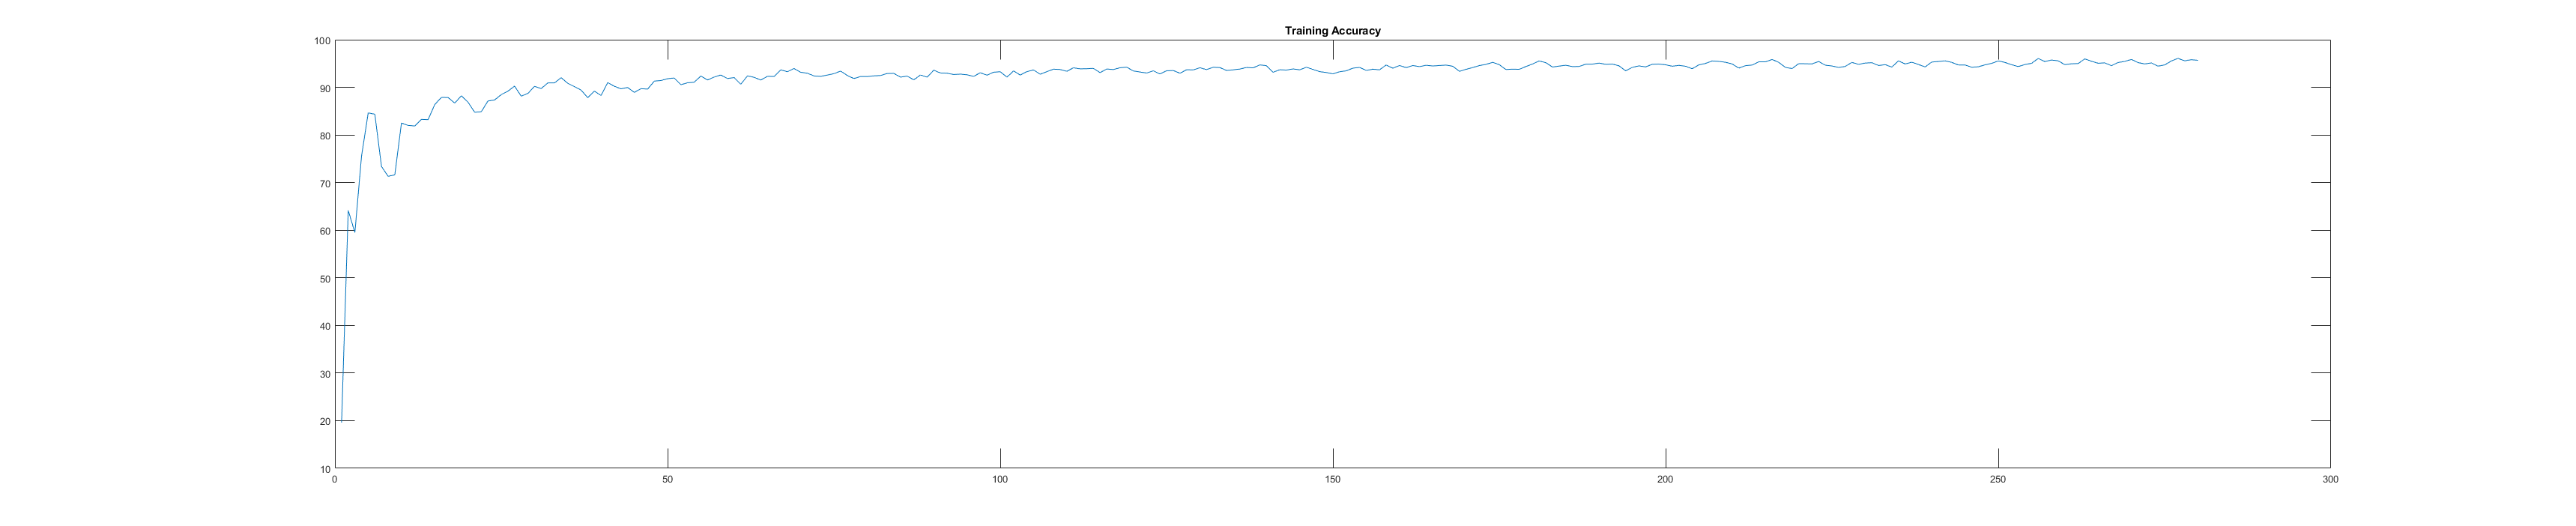

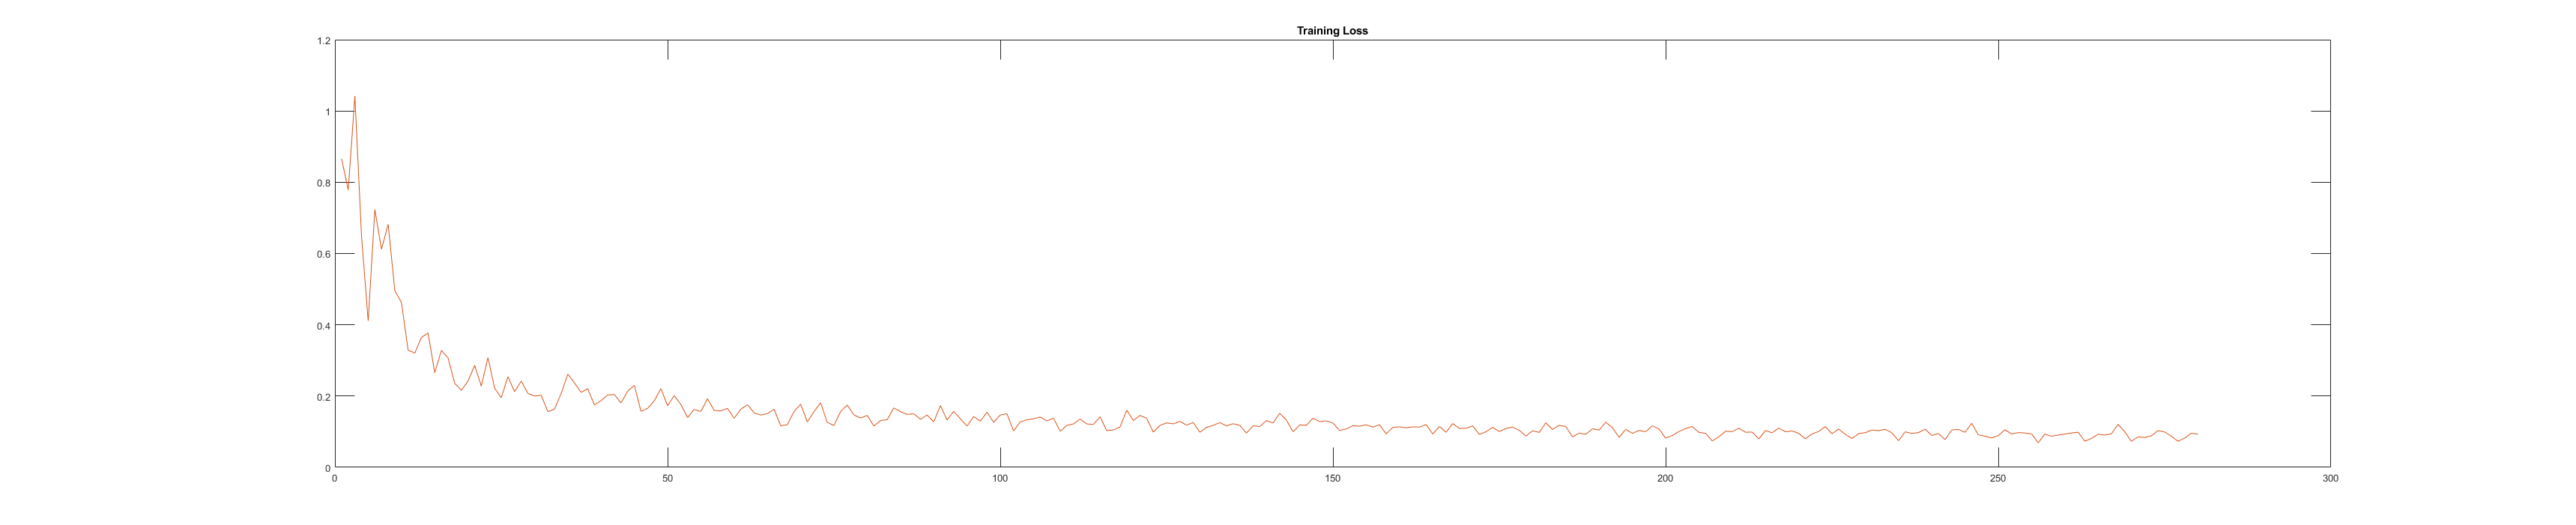

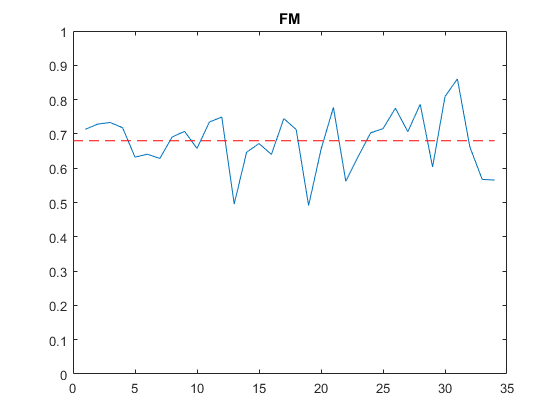

FM mean: 0.68002
FM max: 0.86037
FM min: 0.49133
FM std: 0.08368
accuracy: 95.6745
loss: 0.093162


accuracy_inceptionresnetv2 = 95.6745

loss_inceptionresnetv2 = 0.0932

FM_mean_inceptionresnetv2 = 0.6800

[accuracy_inceptionresnetv2,loss_inceptionresnetv2,FM_mean_inceptionresnetv2]=figureAccAndLoss(info_inceptionresnetv2,FM_test_inceptionresnetv2)

# Plot

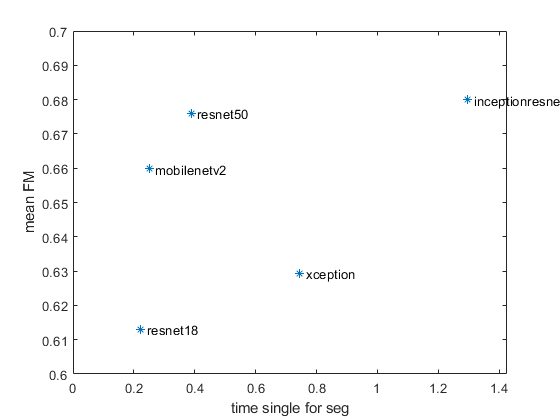

figure;
plot([compTime_resnet50 compTime_resnet18 compTime_mobilenetv2 compTime_xception compTime_inceptionresnetv2]/length(f_test),[FM_mean_resnet50 FM_mean_resnet18 FM_mean_mobilenetv2 FM_mean_xception FM_mean_inceptionresnetv2],'*')
text(([compTime_resnet50 compTime_resnet18 compTime_mobilenetv2 compTime_xception compTime_inceptionresnetv2]/length(f_test))+0.02,[FM_mean_resnet50 FM_mean_resnet18 FM_mean_mobilenetv2 FM_mean_xception FM_mean_inceptionresnetv2],{'resnet50' 'resnet18' 'mobilenetv2' 'xception' 'inceptionresnetv2' })
xlim([0 1.1*max([compTime_resnet50 compTime_resnet18 compTime_mobilenetv2 compTime_xception compTime_inceptionresnetv2]/length(f_test))])
ylim([0.6 0.7])
xlabel('time single for seg')
ylabel('mean FM')

% hold on
% xcircles=[compTime_resnet50 compTime_resnet18 compTime_mobilenetv2 compTime_xception compTime_inceptionresnetv2]/length(f_test);
% ycircles=[FM_mean_resnet50 FM_mean_resnet18 FM_mean_mobilenetv2 FM_mean_xception FM_mean_inceptionresnetv2];
% radii=[numel(net_resnet50.Layers) numel(net_resnet18.Layers) numel(net_mobilenetv2.Layers) numel(net_xception.Layers) numel(net_inceptionresnetv2.Layers)];
% radii=radii/(100*max(radii));
% colors = {'b','r','g','y','k'}; 
% viscircles([xcircles' ycircles'], radii);
% hold off